clear, clc

## LOAD DATA

MVC = '10';
path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Data';
name = ['trial' MVC '_decomposed'];
load([path '\' name '.mat'])
name = ['trial' MVC];
load([path '\' name '.mat'])
clear path, clear name

## PLOT TIME VS REDUCED IPTS AND PLOT VECTOR VS COMPLETE IPTS

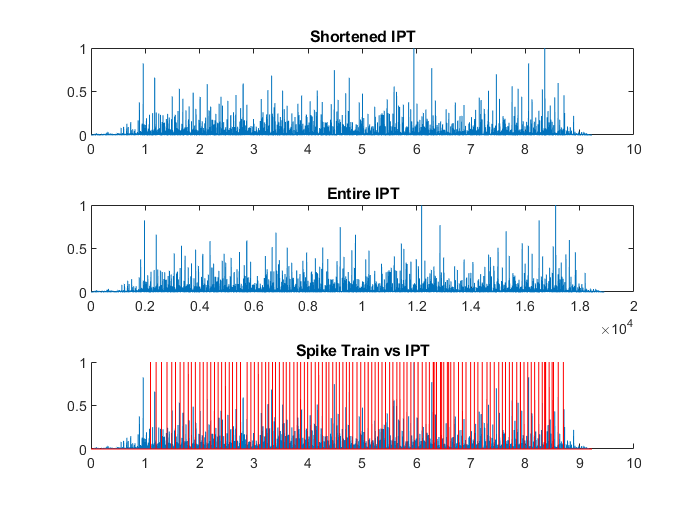

trial_num = 1;  % 5 Trial total
n_neurons = length(MUPulses{trial_num});
neuron_num = 27;

for i = trial_num
    spikeTrain = zeros(1,length(t{i}));
    for j = neuron_num
        spikeTrain(MUPulses{i}{j}) = 1;
        figure, clf
        subplot(3,1,1)
        plot(t{i},IPTs{i}(j,1:length(t{i})))
        title('Shortened IPT')
        subplot(3,1,2)
        plot(1:length(IPTs{i}(j,:)),IPTs{i}(j,:))
        title('Entire IPT')
        subplot(3,1,3), hold on
        plot(t{i},IPTs{i}(j,1:length(t{i})))
        plot(t{i},spikeTrain,'r')
        title('Spike Train vs IPT')
        hold off
    end
end

## CORRELATION BETWEEN SPIKE TRAIN VS IPT

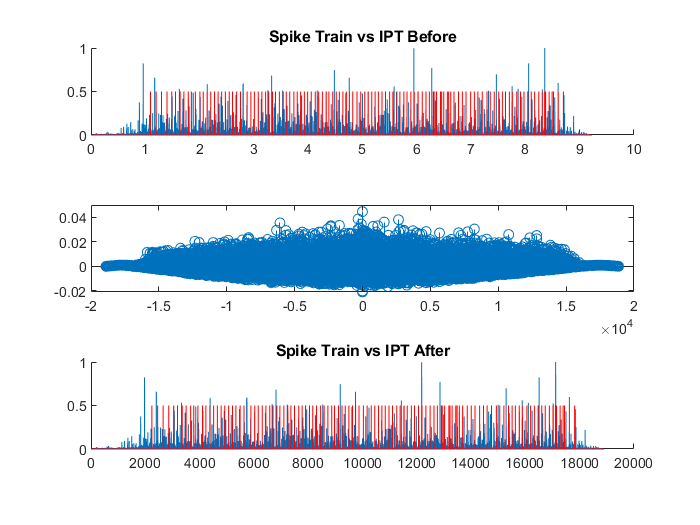

for i = trial_num
    spikeTrain = zeros(1,length(t{i}));
    for j = neuron_num
        spikeTrain(MUPulses{i}{j}) = 0.5;
        figure, clf
        subplot(3,1,1), hold on
        plot(t{i},IPTs{i}(j,1:length(t{i})))
        plot(t{i},spikeTrain,'r')
        title('Spike Train vs IPT Before')
        hold off
        subplot(3,1,2)
        [c,lag] = xcorr(IPTs{i}(j,1:length(t{i}))-mean(IPTs{i}(j,1:length(t{i}))),...
            spikeTrain-mean(spikeTrain),'normalized');
        stem(lag,c)
        [~,idx] = max(c);
        subplot(3,1,3), hold on
        plot(IPTs{i}(j,1:length(t{i})))
        plot((1:length(spikeTrain))+lag(idx),spikeTrain,'r')
        title('Spike Train vs IPT After')
        hold off
    end
end

## PLOT IPTS WITH AND WITHOUT DISCHARGE USING MUPULSES

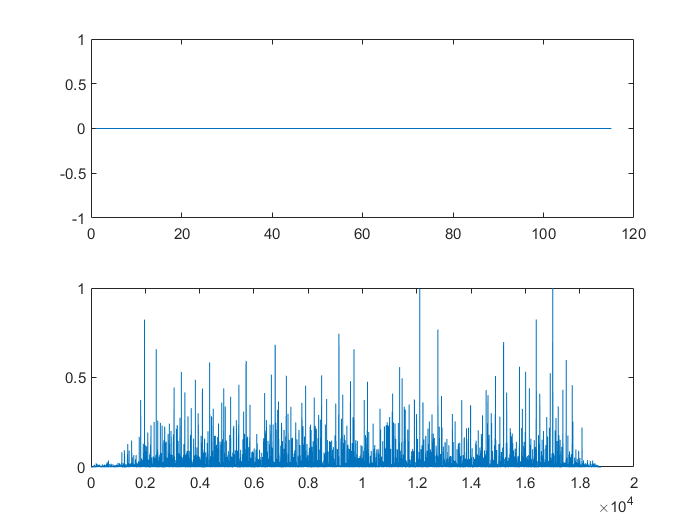

t_Dis = 0

t_noDis = 0.0022

t_t = 0

PNR = -Inf

for i = trial_num
    for j = neuron_num
        figure, clf
        t_hat = IPTs{i}(j,1:end-15);
        Discharge = MUPulses{i}{j};
        noDischarge = setdiff(1:length(t_hat),Discharge);
        subplot(2,1,1)
        plot(t_hat(Discharge))
        subplot(2,1,2)
        plot(t_hat(noDischarge))
        % PNR
        t_Dis = mean(t_hat(Discharge).^2)
        t_noDis = mean(t_hat(noDischarge).^2)
        t_t = t_Dis/t_noDis
        PNR = 10*log10(t_t)
    end
end

## PLOT IPTS WITH AND WITHOUT DISCHARGE NO USING MUPULSES

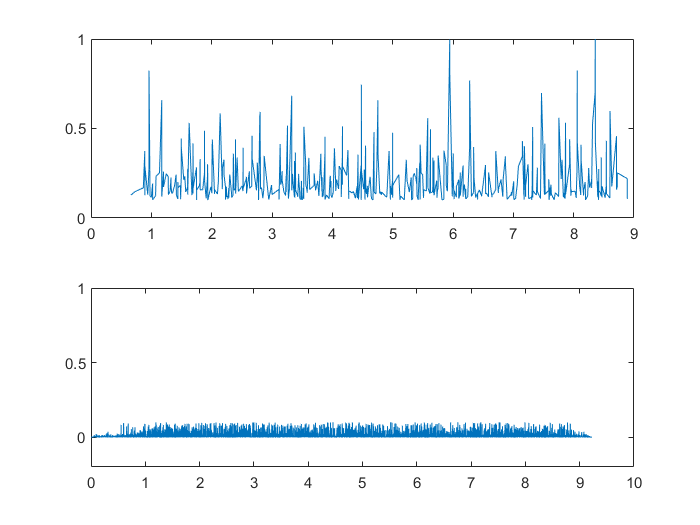

t_Dis = 0.0670

t_noDis = 2.5844e-04

t_t = 259.3391

PNR = 24.1387

for i = trial_num
    for j = neuron_num
        figure, clf
        t_hat = IPTs{i}(j,1:length(t{i}));
        Discharge = find(t_hat > 0.1);
        noDischarge = setdiff(1:length(t_hat),Discharge);
        subplot(2,1,1)
        plot(t{i}(Discharge),t_hat(Discharge))
        subplot(2,1,2)
        plot(t{i}(noDischarge),t_hat(noDischarge))
        ylim([-0.2,1])
        % PNR
        t_Dis = mean(t_hat(Discharge).^2)
        t_noDis = mean(t_hat(noDischarge).^2)
        t_t = t_Dis/t_noDis
        PNR = 10*log10(t_t)
    end
end

## PLOT DATA IN RECORDED DATA

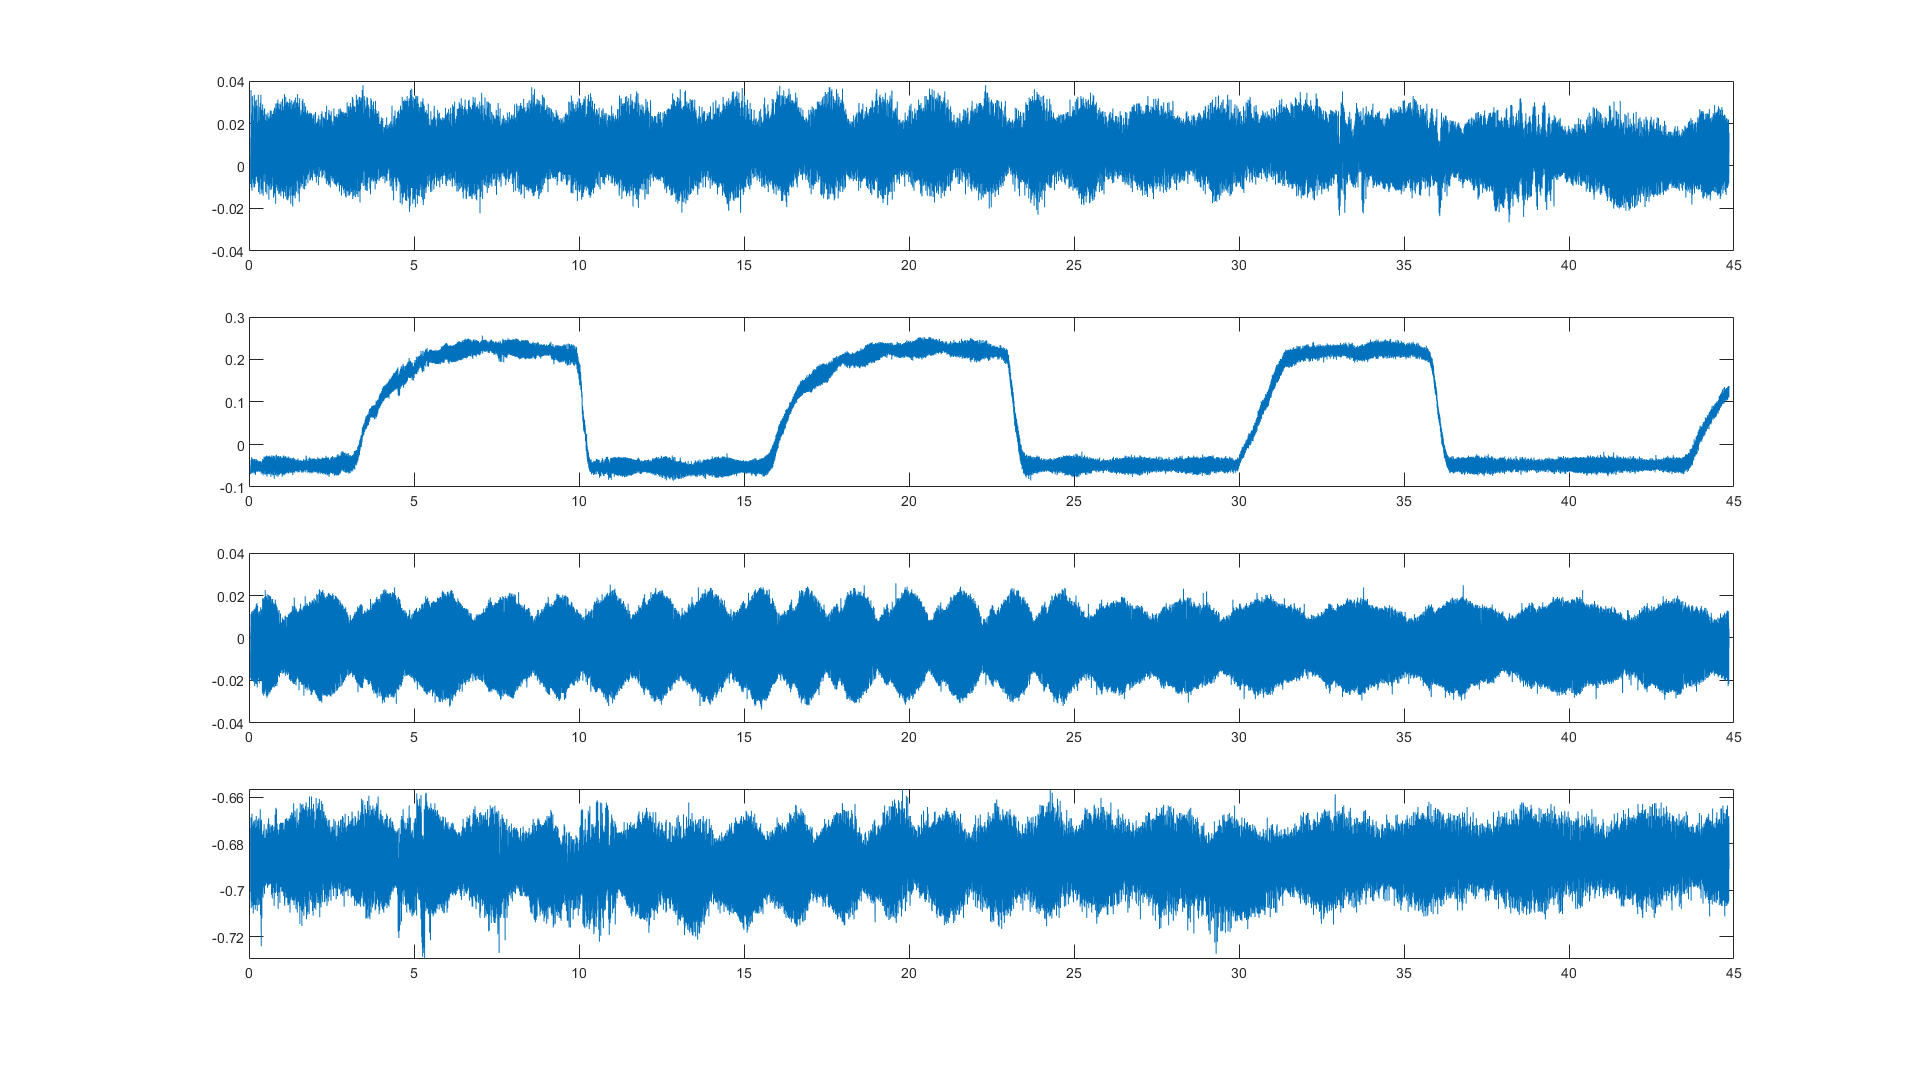

figure, clf
for i = 2:size(recordedData{1},2)
    subplot(4,1,i-1)
    plot(recordedData{1}(:,1),recordedData{1}(:,i))
end
set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 1, 1]);

## SEPARATE THE FORCE WHERE VALUES OVERPASS ZERO

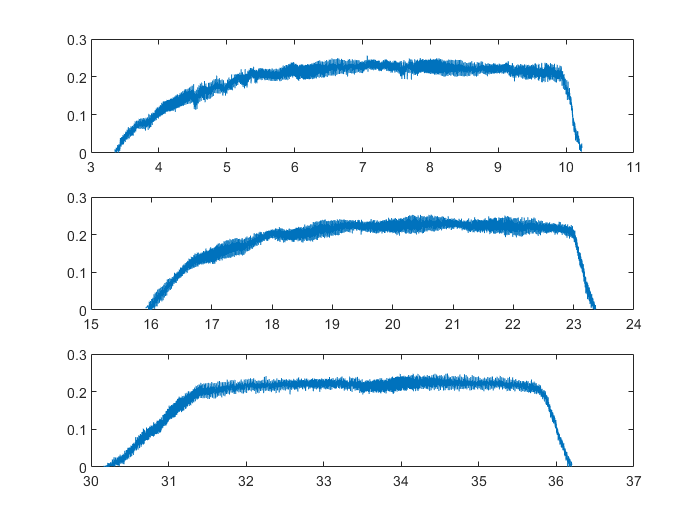

timeForce = recordedData{1}(:,1);
Force = recordedData{1}(:,3);
forceLapse = find(Force > 0);
fsForce = ceil(length(timeForce)/(timeForce(end)-timeForce(1)));
Force_red = Force(forceLapse);
timeForce_red = timeForce(forceLapse);
timeLapse = find(diff(timeForce_red) > 0.5)';  % Find time spaces greater than 2 seconds
Lapse = [1 timeLapse length(Force_red)];
ptn = 1;

figure, clf
for i = 1:length(Lapse)-1
    if (Lapse(i+1)-1)-(Lapse(i)+1) > 4000 && ptn <= 3
        subplot(3,1,ptn)
        plot(timeForce_red(Lapse(i)+1:Lapse(i+1)-1),Force_red(Lapse(i)+1:Lapse(i+1)-1))
        ptn = ptn+1;
    end
end

## PLOT FORCE SEPARATED BY STAMPS

timeStamps_transformed = round(timeStamps*size(recordedData{1},1)/size(recordedData{2},2));

figure, clf
for i = 1:size(timeStamps,1)
    subplot(5,1,i)
    lapse = timeStamps_transformed(i,1):timeStamps_transformed(i,2);
    plot(recordedData{1}(lapse,1),recordedData{1}(lapse,3))
end

## PLOT FORCE UPPER PEAKS

timeStops = [4,12.5;17,28;32,46];
timeForce = recordedData{1}(:,1);
Force = recordedData{1}(:,3);
fs = ceil(length(timeForce)/(timeForce(end)-timeForce(1)));
figure, clf
for i = 1
    subplot(3,1,i), hold on
    forceLapse = find(Force > 0);
    timeLapse = find(timeForce > timeStops(i,1) & timeForce < timeStops(i,2));
    lapse = intersect(forceLapse,timeLapse);
    w = hann(round(0.008*fs));
    force_filtered = normalize(filtfilt(w,1,Force(lapse)),'range');
    plot(timeForce(lapse),force_filtered)
end
set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 1, 1]);